# Analyzing Re-Alignment

## Recollect all data


load('results_BrainBonus2.mat')
recollect_data

## calculation condition phases

theta_phases_condition = zeros([length(times), max(condition_positions), length(results)]);

freq_min = 4.5;
freq_max = 8;
for subj_ind = 1:length(results)
    theta_phases_subject = get_hilbert_phase(results{subj_ind}.trials, freq_min, freq_max, SamplingInterval);
    for cond_ind = 1:size(theta_phases_condition,2)
        theta_phases_condition(:,cond_ind,subj_ind) = circ_mean(theta_phases_subject(:,results{subj_ind}.condition_positions == cond_ind),[],2);
    end
end

erp_phases_condition = [];
for subj_ind = 1:length(results)
    for cond_ind = 1:size(theta_phases_condition,2)
        erp_phases_condition(:,cond_ind,subj_ind) = get_hilbert_phase(mean(results{subj_ind}.trials(:,:,results{subj_ind}.condition_positions == cond_ind),3), freq_min, freq_max, SamplingInterval);
    end
end


## Testing for different in phases

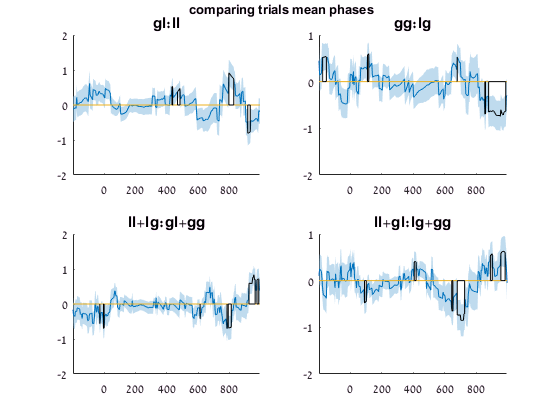

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(theta_phases_condition, 3, 1, u, t, p_thresh, n, false);
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(theta_phases_condition, 4, 2, u, t, p_thresh, n, false);
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(theta_phases_condition, 1:2, 3:4, u, t, p_thresh, n, false);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(theta_phases_condition, [1 3], [2 4], u, t, p_thresh, n, false);
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean phases'

p_thresh = 0.01;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(theta_phases_condition, 3, 1, u, t, p_thresh, n, true)

No significant clusters found.


title 'gl:ll'
subplot(2,2,2)
show_perm_phases(theta_phases_condition, 4, 2, u, t, p_thresh, n, true)

No significant clusters found.


title 'gg:lg'
subplot(2,2,3)
show_perm_phases(theta_phases_condition, 1:2, 3:4, u, t, p_thresh, n, true)
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(theta_phases_condition, [1,3], [2,4], u, t, p_thresh, n, true)

No significant clusters found.


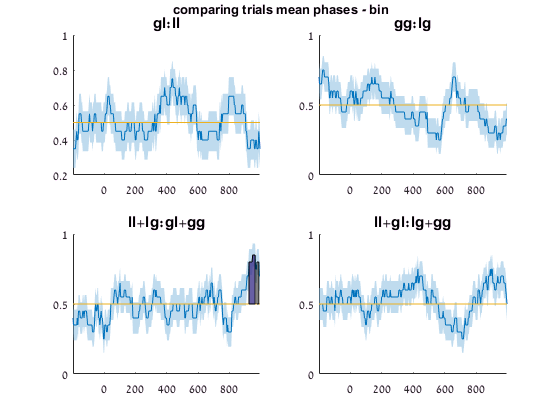

title 'll+gl:lg+gg'
title_subplots 'comparing trials mean phases - bin'

## comparing to ERP

% p_thresh = 0.005;
% n = 1e3;

show_perm_results(total_erps, 3, 1, u, t)

Cluster 1: time points 131 to 153, t-sum = 65.1919, p-value = 0.0150985.
Cluster 2: time points 8 to 10, t-sum = 5.79681, p-value = 0.706929.


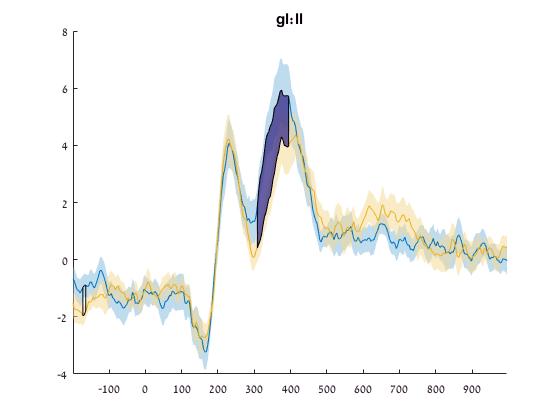

title 'gl:ll'

show_perm_results(total_erps, 4, 2, u, t)

Cluster 1: time points 145 to 207, t-sum = 246.58, p-value = 0.00019998.
Cluster 2: time points 106 to 111, t-sum = 12.7849, p-value = 0.482452.


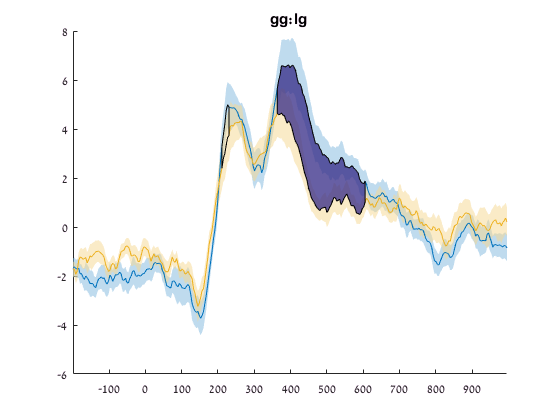

title 'gg:lg '

show_perm_results(total_erps, 1:2, 3:4, u, t)

Cluster 1: time points 302 to 307, t-sum = 14.9038, p-value = 0.407559.
Cluster 2: time points 36 to 41, t-sum = 13.2875, p-value = 0.450655.
Cluster 3: time points 93 to 98, t-sum = 11.7926, p-value = 0.49765.
Cluster 4: time points 256 to 260, t-sum = 10.1364, p-value = 0.549845.
Cluster 5: time points 237 to 238, t-sum = 3.83969, p-value = 0.785721.
Cluster 6: time points 269 to 269, t-sum = 1.78178, p-value = 0.867813.
Cluster 7: time points 241 to 241, t-sum = 1.73487, p-value = 0.881712.


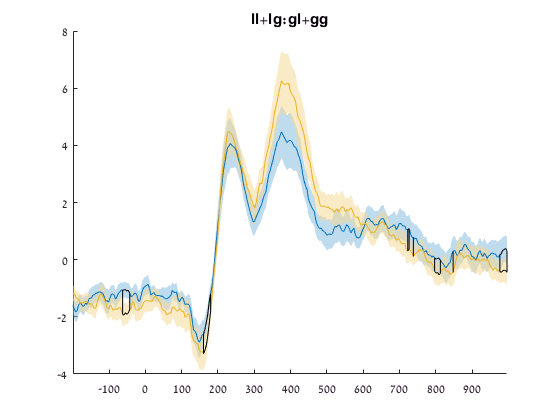

title 'll+lg:gl+gg'

show_perm_results(total_erps, [1,3], [2,4], u, t)

Cluster 1: time points 245 to 271, t-sum = 75.254, p-value = 0.010499.
Cluster 2: time points 67 to 80, t-sum = 31.3703, p-value = 0.145185.
Cluster 3: time points 24 to 29, t-sum = 14.6905, p-value = 0.420958.
Cluster 4: time points 87 to 89, t-sum = 6.4322, p-value = 0.694131.
Cluster 5: time points 291 to 292, t-sum = 3.74544, p-value = 0.822018.
Cluster 6: time points 22 to 22, t-sum = 1.79925, p-value = 0.887411.


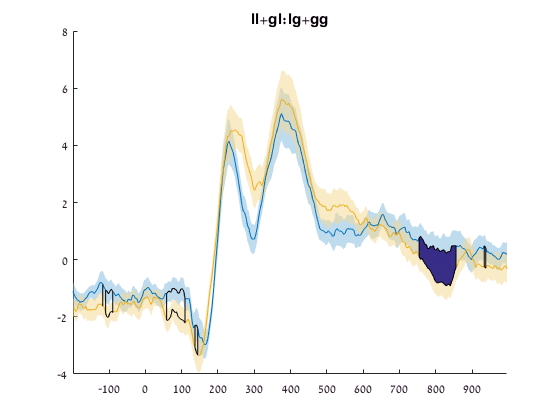

title 'll+gl:lg+gg'

ERP phases

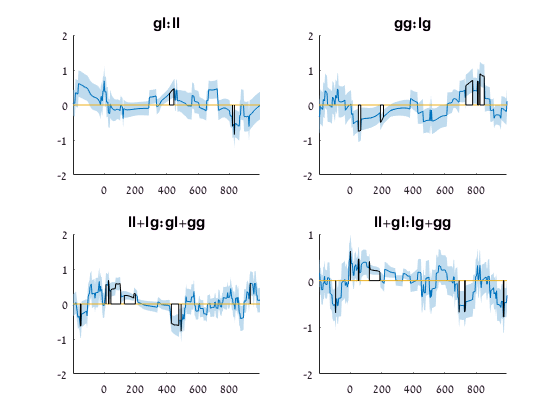

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(erp_phases_condition, 3, 1, u, t, p_thresh, n, false)
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(erp_phases_condition, 4, 2, u, t, p_thresh, n, false)
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(erp_phases_condition, 1:2, 3:4, u, t, p_thresh, n, false)
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(erp_phases_condition, [1,3], [2,4], u, t, p_thresh, n, false)
title 'll+gl:lg+gg'

title_subplots 'comparing ERP phases'


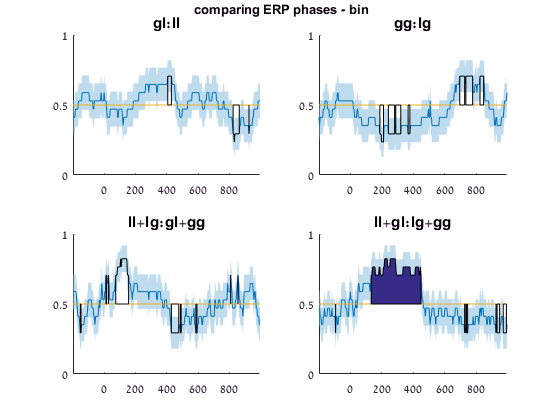

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(erp_phases_condition(:,:,1:17), 3, 1, u, t, p_thresh, n, true)
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(erp_phases_condition(:,:,1:17), 4, 2, u, t, p_thresh, n, true)
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(erp_phases_condition(:,:,1:17), 1:2, 3:4, u, t, p_thresh, n, true)
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(erp_phases_condition(:,:,1:17), [1,3], [2,4], u, t, p_thresh, n, true)
title 'll+gl:lg+gg'
title_subplots 'comparing ERP phases - bin'

## Testing phases using wavelets

phases_condition = zeros([length(freqs), length(times), max(condition_positions), length(results)]);
s_ = @squeeze;

s_ =     @squeeze


for subj_ind = 1:length(results)
    phases_subject = s_(results{subj_ind}.phases);   
    for cond_ind = 1:size(phases_condition,3)
        phases_condition(:,:,cond_ind,subj_ind) = circ_mean(phases_subject(:,:,results{subj_ind}.condition_positions == cond_ind),[],3);
    end
end
% 
% erp_phases_condition = [];
% for subj_ind = 1:length(results)
%     for cond_ind = 1:size(theta_phases_condition,2)
%         erp_phases_condition(:,cond_ind,subj_ind) = get_hilbert_phase(mean(results{subj_ind}.trials(:,:,results{subj_ind}.condition_positions == cond_ind),3), freq_min, freq_max, SamplingInterval);
%     end
% end


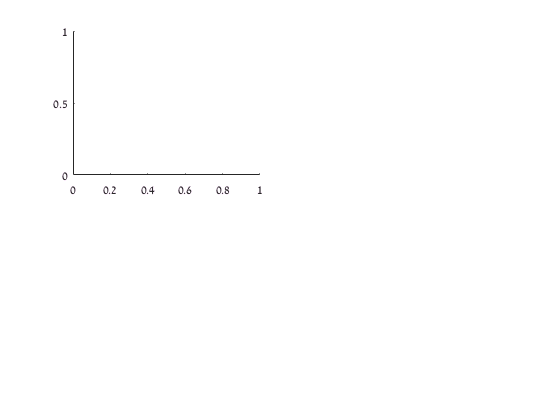

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)

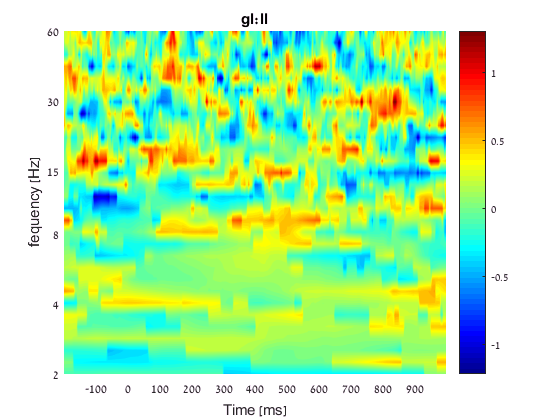

show_perm_phases(phases_condition, 3, 1, u, t, p_thresh, n, true, freqs);
title 'gl:ll'

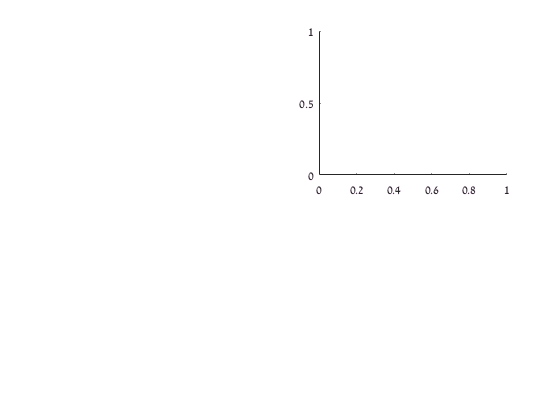

subplot(2,2,2)

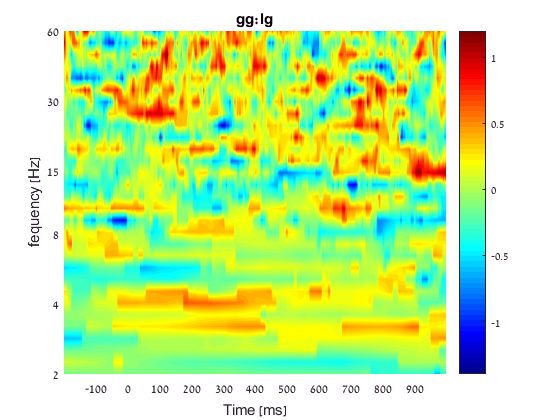

show_perm_phases(phases_condition, 4, 2, u, t, p_thresh, n, true, freqs);
title 'gg:lg'

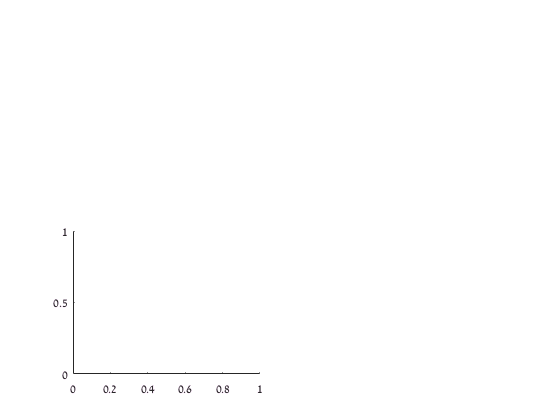

subplot(2,2,3)

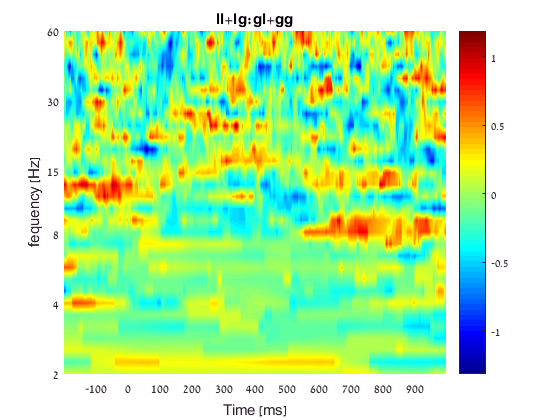

show_perm_phases(phases_condition, 1:2, 3:4, u, t, p_thresh, n, true, freqs);
title 'll+lg:gl+gg'

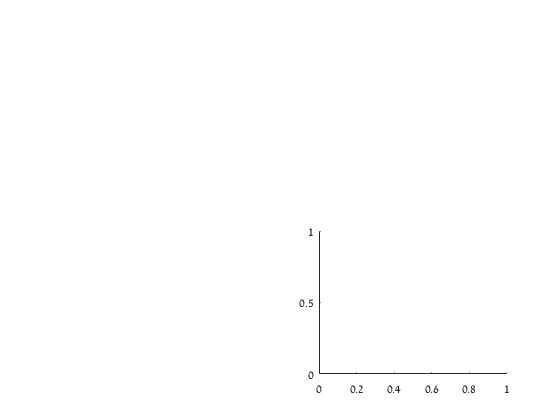

subplot(2,2,4)

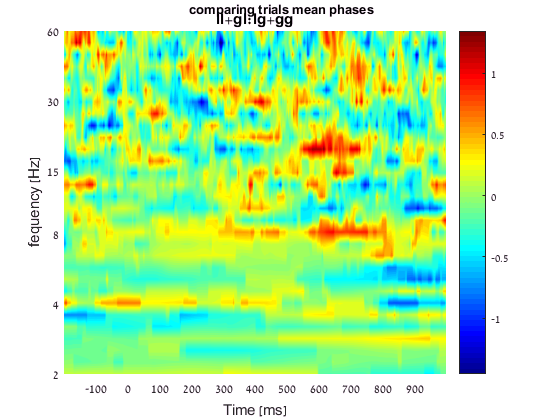

show_perm_phases(phases_condition, [1 3], [2 4], u, t, p_thresh, n, true, freqs);
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean phases - bin'

function show_perm_phases(data, left_inds, right_inds, u, t, p_thresh, num_permutations, is_bin, freqs)

set_default('is_bin', false);
set_default('p_thresh', 0.05);
set_default('num_permutations', 1e4);

is2dData = ndims(data) == 4;

if left_inds<0
    left_inds = find(1:4 ~= -left_inds);
end
if right_inds<0
    right_inds = find(1:4 ~= -right_inds);
end

if is2dData
    trial_g_1 = squeeze(circ_mean(data(:,u,left_inds, :),[], 3));
    if right_inds ~= 0
        trial_g_2 = squeeze(circ_mean(data(:,u,right_inds, :),[], 3));
    end    
else
    trial_g_1 = squeeze(circ_mean(data(u,left_inds, :),[], 2));
    if right_inds ~= 0
        trial_g_2 = squeeze(circ_mean(data(u,right_inds, :),[], 2));
    end
end


if right_inds == 0
    trial_g_2 = [];
    trial_g = trial_g_1;
else
    trial_g = circ_dist(trial_g_1,trial_g_2);
end

if is_bin
    trial_g = 1*(trial_g>0);
    thresh_g = 0.5;
else 
    thresh_g = 0;
end

if is2dData
    permutest_2dplot(trial_g, thresh_g, true, p_thresh, num_permutations, true, inf, true, t, freqs);
else
    permutest_plot(trial_g, thresh_g, true, p_thresh, num_permutations, true, inf, t, false);
end

end


function test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, t0, freq_min, freq_max, align_by_erp)


set_default('align_by_erp', false)

t_zero = t0;
N_subjects = length(results);
t=times(u);
total_powers_aligned = zeros([length(freqs), length(times), N_subjects]);

sub_powers_aligned = total_powers_aligned;
total_erps_aligned = zeros([ length(times)  N_subjects]);


for sub_ind = 1:N_subjects
    result = results{sub_ind};
    trials = result.trials;
    power_raw = result.power_raw;
    
    if align_by_erp
        phase_shifts = get_hilbert_phase_shift(mean(trials,3), freq_min, freq_max, SamplingInterval);
        phase_shifts = repmat(phase_shifts,1,size(trials,3));
    else
        phase_shifts = get_hilbert_phase_shift(trials, freq_min, freq_max, SamplingInterval);
    end
    shift = phase_shifts(find(times>t_zero,1),:);
    aligned_trials = align_trials_by_shift(trials, shift);
    aligned_erp = mean(aligned_trials(:,1,:),3);
    aligned_power = align_power_by_shift(power_raw, shift);
    aligned_power = norm_power_bl_range(squeeze(aligned_power), bl_range);
    
    sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);
    sub_aligned_power = getPowerSpectra(sub_trials_aligned', SamplingInterval./1000, freqs);
    sub_aligned_power = norm_power_bl_range(sub_aligned_power, bl_range);
    
    total_powers_aligned(:,:,sub_ind) = squeeze(aligned_power);
    sub_powers_aligned  (:,:,sub_ind) = squeeze(sub_aligned_power);
    total_erps_aligned(:,sub_ind) = aligned_erp;
    
end

title_freq = sprintf('@ t=%d ms, f=%.1f-%.1f Hz', t_zero, freq_min, freq_max);
if align_by_erp
    title_freq = ['shift by subjects'' ERP' title_freq];
end

figure;
show_powers_tight(t, freqs, cat(3, ...
    squeeze(mean(total_powers(:,u,:),3)), ...
    squeeze(mean(sub_powers(:,u,:),3)), ...
    squeeze(mean(total_powers(:,u,:),3))-squeeze(mean(sub_powers(:,u,:),3)), ...
    mean(total_powers_aligned(:,u,:),3), ...
    mean(sub_powers_aligned(:,u,:),3), ...
    mean(total_powers_aligned(:,u,:),3)-mean(sub_powers_aligned(:,u,:),3)),...
    3, title_freq, 'Power [db]', [], ...
    {'total power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'})

figure;
subplot(1,2,1);
varplot(times, squeeze(mean(total_erps,2)))

title({'original trials'})
subplot(1,2,2);
varplot(times, total_erps_aligned)
title({'aligned trials ' title_freq})

end

function norm_power = norm_power_bl_range(power, bl_range)
bl_values = mean(mean(power(:, bl_range, :),3),2);
norm_power = 10 * log10(bsxfun(@rdivide,mean(power,3),bl_values));
end

